create map

grid = OctoGrid(2,2,2,10);

% add wall
grid.addBox(0.25, 0.25, 0, 0.5, 0.5, 1.5);

grid.addBox(1.4, 0.25, 0, 0.25, 1.4, 1.5);
grid.addBox(0.6, 1.4, 0, 0.8, 0.25, 1.5);

generate kernels

rep_kernels = REP_kernels()

rep_kernels = 1×3 cell array
    {7×7×7 double}    {7×7×7 double}    {7×7×7 double}


display 2d obstacles

image2d = grid.grid(:,:,5)

image2d =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0    

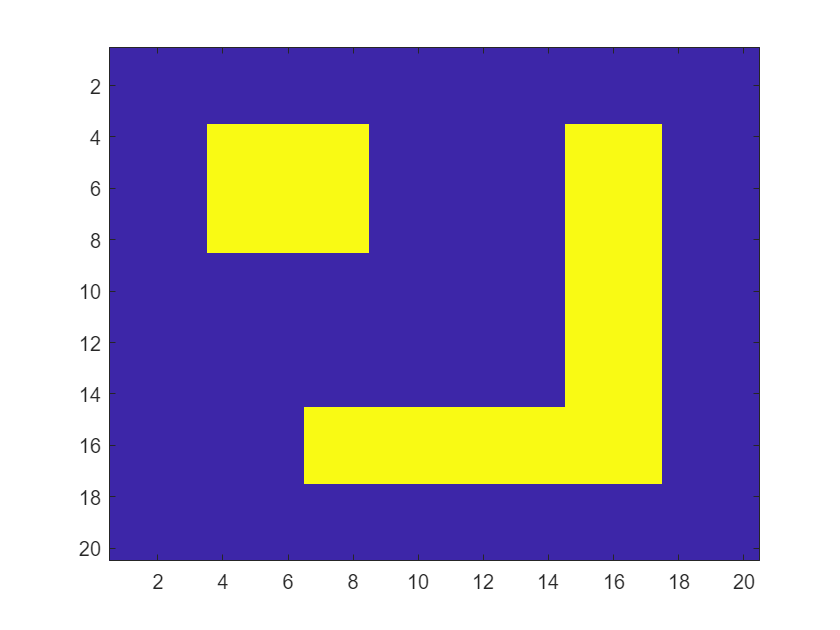

imagesc(image2d)

field calculation

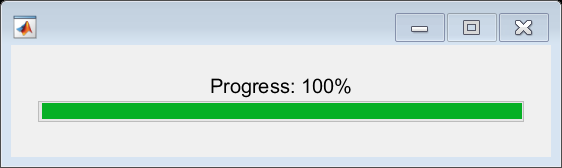

x = 0.1:0.01:2;
y = 0.1:0.01:2;
z = 1;

rep_values_2Dx = [];
rep_values_2Dy = [];

rep_values_2Dx_i = [];
rep_values_2Dy_i = [];

map_matrix = [];

% Initialize waitbar
h = waitbar(0, 'Progress: 0%');

for j = x
    rep_values_1D = [];
    rep_values_1D_i = [];

    map_matrix_1D = [];

    for i = y
%         tic()
        rep_values_1D = [rep_values_1D REP_field_calculation(grid, rep_kernels, [j,i,z],'interpolation_mode', false)'];
        rep_values_1D_i = [rep_values_1D_i REP_field_calculation(grid, rep_kernels, [j,i,z],'interpolation_mode', true)'];

        map_matrix_1D = [map_matrix_1D grid.grid(round(i*grid.resolution), round(j*grid.resolution), 0.5*grid.resolution)];

%         toc()
    end
    rep_values_2Dx = [rep_values_2Dx ; rep_values_1D(1,:)];
    rep_values_2Dy = [rep_values_2Dy ; rep_values_1D(2,:)];

    rep_values_2Dx_i = [rep_values_2Dx_i ; rep_values_1D_i(1,:)];
    rep_values_2Dy_i = [rep_values_2Dy_i ; rep_values_1D_i(2,:)];

    map_matrix = [map_matrix ; map_matrix_1D];

    % Update progress bar
    waitbar(j / x(end), h, sprintf('Progress: %d%%', round(j / x(end) * 100)));
end

create the figure

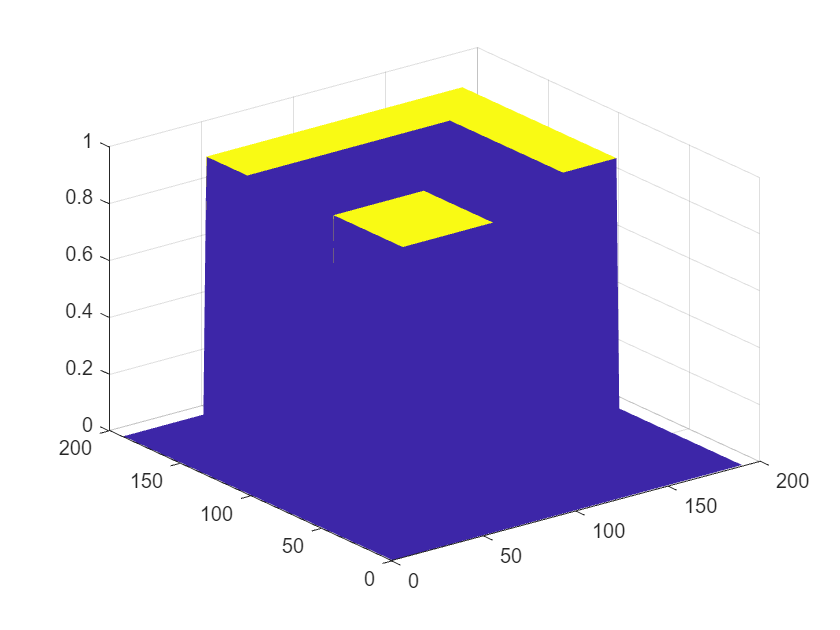

surf(map_matrix, 'EdgeColor', 'none')

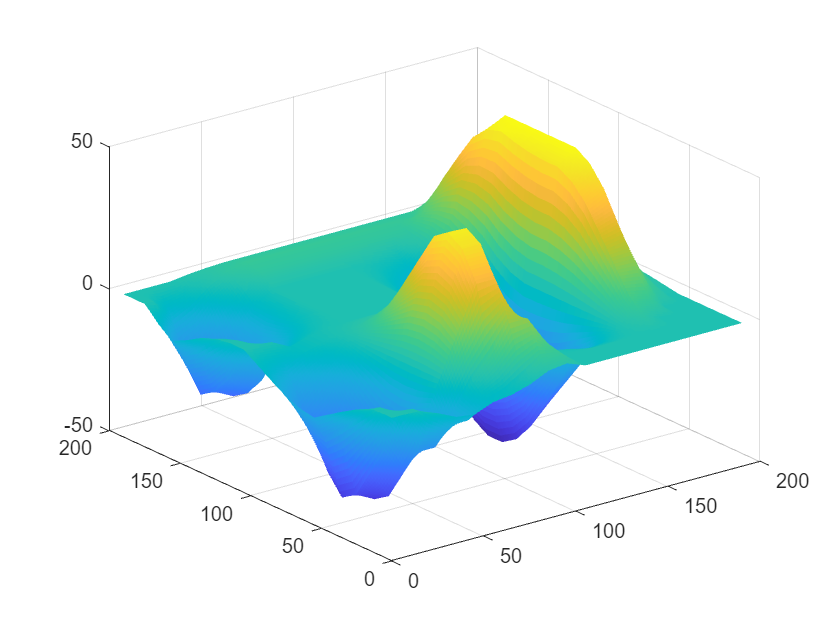

surf(((rep_values_2Dy_i )), 'EdgeColor', 'none')

display vector field

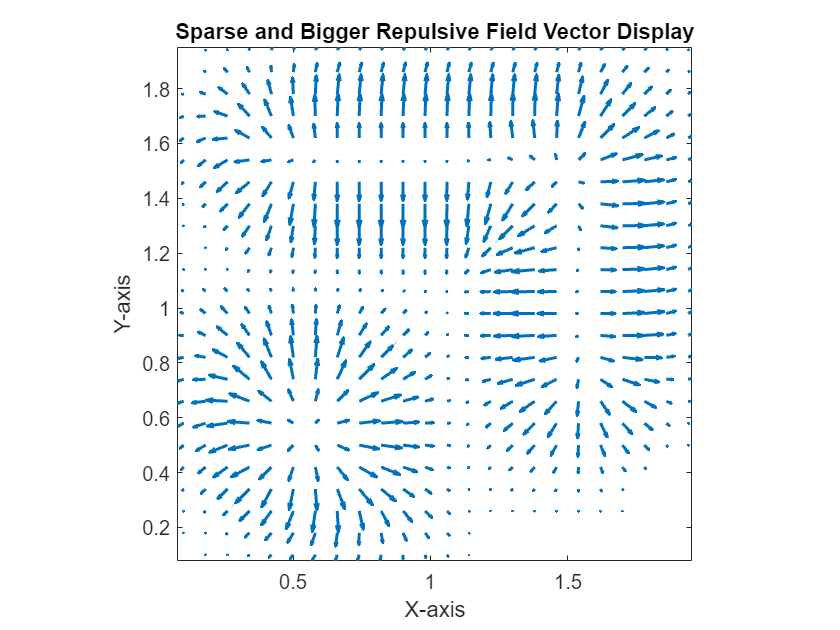

figure()
% Assuming x and y are your 1x191 vectors
[X, Y] = meshgrid(x, y); % This step might be redundant if x and y are already grid vectors

% rep_values_2Dx_i and rep_values_2Dy_i are your 191x191 matrices for the vector components
U = rep_values_2Dx_i;
V = rep_values_2Dy_i;

% Define step size for sparseness
stepSize = 8; % Adjust this to make the grid more or less sparse

% Sample the matrices to reduce density
X_sparse = X(1:stepSize:end, 1:stepSize:end);
Y_sparse = Y(1:stepSize:end, 1:stepSize:end);
U_sparse = rep_values_2Dx_i(1:stepSize:end, 1:stepSize:end);
V_sparse = rep_values_2Dy_i(1:stepSize:end, 1:stepSize:end);
magnitude_sparse = sqrt(U_sparse.^2+V_sparse.^2)

% Plotting the sparser, bigger vector field
quiver(X_sparse, Y_sparse, V_sparse, U_sparse, 'AutoScale', 'on', 'AutoScaleFactor', 0.8, 'LineWidth', 1.5);
title('Sparse and Bigger Repulsive Field Vector Display');
xlabel('X-axis');
ylabel('Y-axis');
axis equal tight;

display vector field using loop, add colors

figure();
% Assuming x and y are your 1x191 vectors
[X, Y] = meshgrid(x, y); % This step might be redundant if x and y are already grid vectors

% rep_values_2Dx_i and rep_values_2Dy_i are your 191x191 matrices for the vector components
U = rep_values_2Dx_i;
V = rep_values_2Dy_i;

% Define step size for sparseness
stepSize = 5; % Adjust this to make the grid more or less sparse

% Sample the matrices to reduce density
X_sparse = X(1:stepSize:end, 1:stepSize:end);
Y_sparse = Y(1:stepSize:end, 1:stepSize:end);
U_sparse = U(1:stepSize:end, 1:stepSize:end);
V_sparse = V(1:stepSize:end, 1:stepSize:end);
scale = 0.001

scale = 1.0000e-03

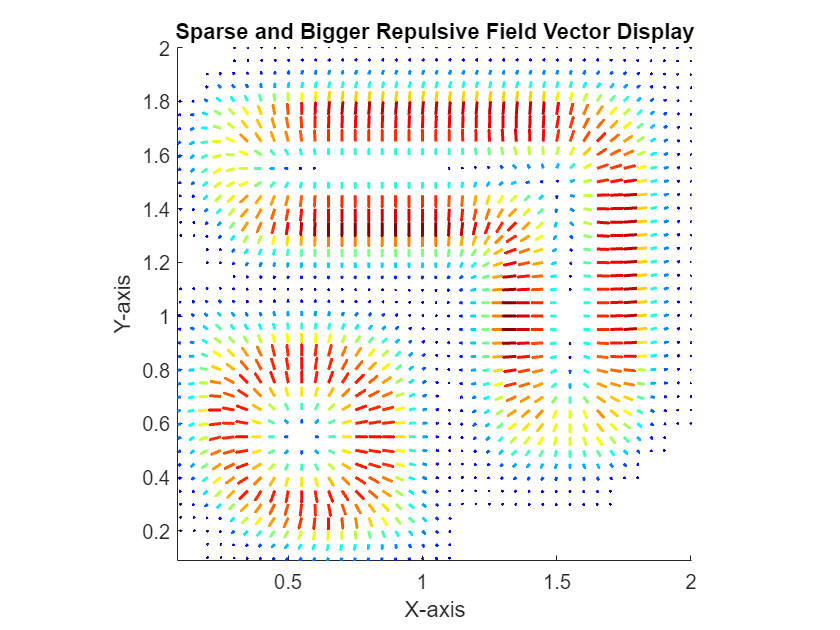

% Calculate the magnitudes of the vectors
magnitudes = sqrt((scale * U_sparse).^2 + (scale * V_sparse).^2);

% Normalize magnitudes for color mapping
maxMagnitude = max(magnitudes(:)); % Find the maximum magnitude
normalizedMagnitudes = magnitudes / maxMagnitude; % Normalize magnitudes to [0, 1]

% Generate a colormap
cmap = jet(256); % Use jet colormap with 256 entries


% Loop over each element in the sparse matrices and plot individually
for i = 1:size(X_sparse, 1)
    for j = 1:size(Y_sparse, 2)
        hold on
        % Map the normalized magnitude to the colormap
        colorIndex = min(max(floor(normalizedMagnitudes(i, j) * size(cmap, 1)), 1), size(cmap, 1));
        arrowColor = cmap(colorIndex, :);
        
        quiver(X_sparse(i, j), Y_sparse(i, j), scale * V_sparse(i, j), scale * U_sparse(i, j), 'AutoScale', 'off', 'LineWidth', 1.5, 'Color', arrowColor);
    end
end

% Finalizing the plot details
title('Sparse and Bigger Repulsive Field Vector Display');
xlabel('X-axis');
ylabel('Y-axis');
axis equal tight;
hold off; % Release the figure window for other plots